# Classify normal and abnormal vibration data

This script demonstrates the complete workflow for developing an embedded machine learning application,including acquiring the data, extracting features, exploring various algorithms, tuning to get a model with good performance, and  deploying the model in a prototype application. Specifically, we develop a classifier of vibration signal from a wind turbine into 'Normal' and 'Abnormal', which could be used in predictive maintenance system to monitor the engineering assets.

THIS SCRIPT IS INTENDED TO BE STEPPED THROUGH SECTION BY SECTION, because of the interactive Signal Analyzer and Classification Learner apps that it calls. If you try to run the complete script, errors are likely to occur.

The figure below shows the high-level architecture and a screenshot from the prototype.

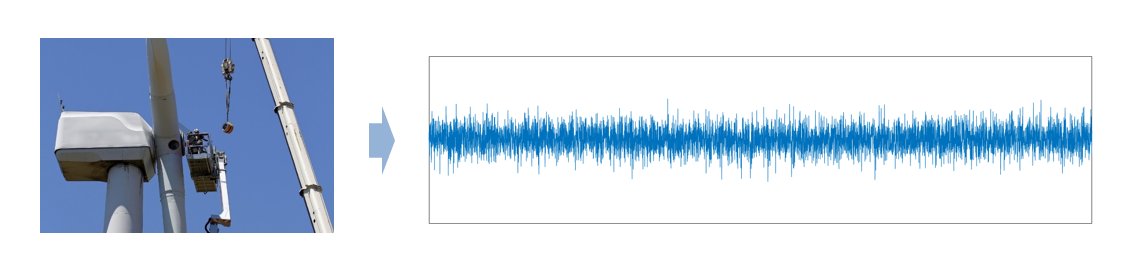

Copyright 2019 The MathWorks, Inc.

The demo is structured according to the four phases of the typical machine learning workflow:

- Access and Explore Data

- Preproess Data

- Develop Predictive Models

- Integrate Models with Systems

The figure below shows which additional MATLAB toolboxes we will leverage in the various phases of the workflow.

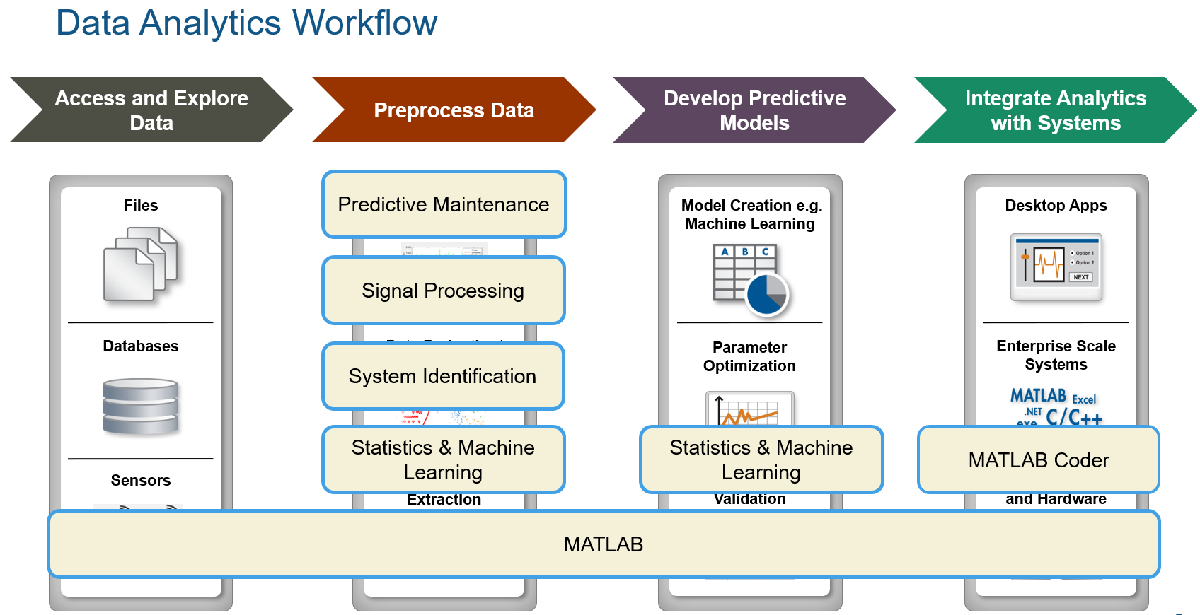

## 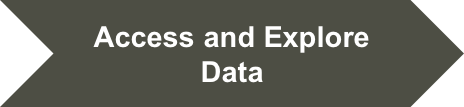

Load the preprocessed data saved in  `sampleData.mat. See` `dataPreparation.mlx for the details.`

load('sampleData.mat');

Take two sample vibration signal for a quick comparison.

vib1 = sampleData.vibration{1}.Variables; % Normal
vib2 = sampleData.vibration{25}.Variables; % Abnormal

## 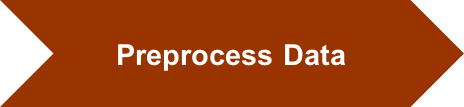

## What do the signals look like in the frequency domain?

To explore what we might use to distinguish these signals with a classifier, let's look at their frequency content. To this end, you can use MATLAB's [Signal Analyzer](https://www.mathworks.com/help/signal/ug/getting-started-with-signal-analyzer-app.html) app to inspect and compare the power spectrum of the two signals.

signalAnalyzer(vib1,vib2)

Once the app has loaded, display the signals in two separate panels (use the Grid button on the left upper corner), and then generate the Spectrum underneath the waveform (by clicking the corresponding button).

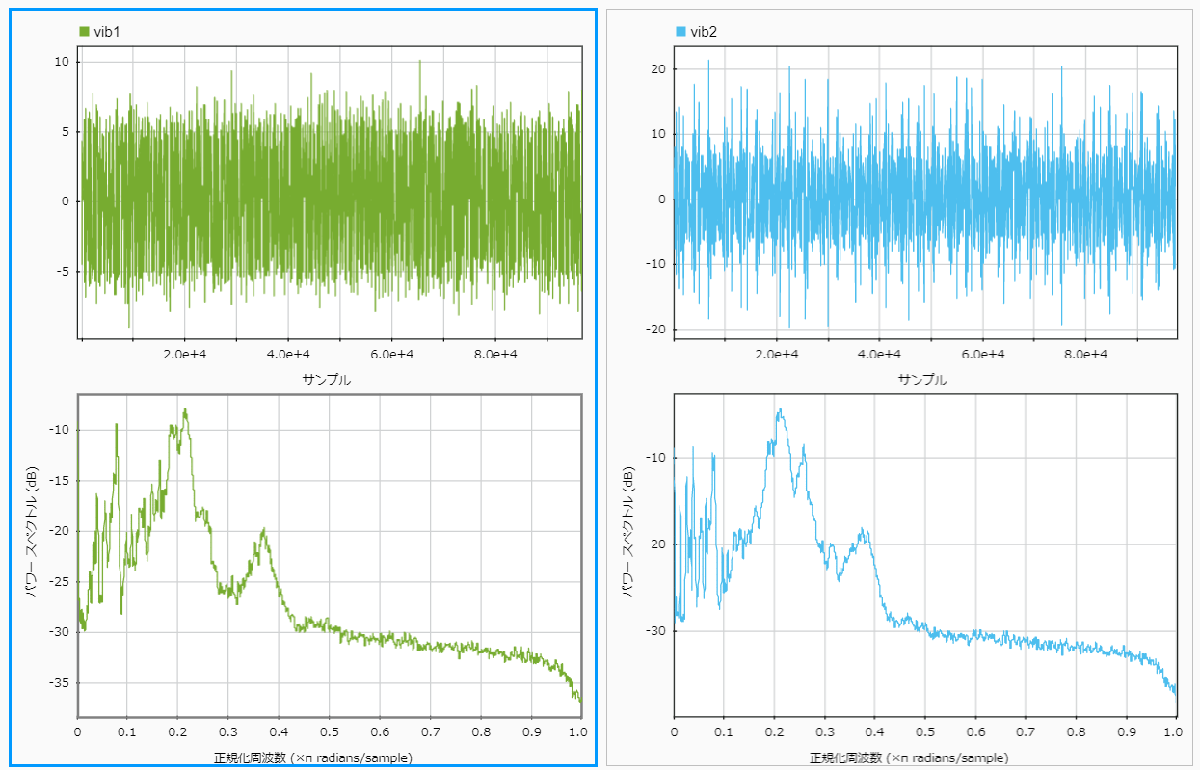

## 

## Extract features from raw vibration signals

Next we need to extract features from the raw recordings. We use Diagnostic Feature Designer available in Predictive Maintenance Toolbox to process and extract features from the raw vibration signal. The following section extracts features for each recording, and splits each recording into windows consisting of 0.2 seconds of vibration signal.

To avoid this step, you can simply load the extracted features from `FeatureTable.mat` that we included with the demo.

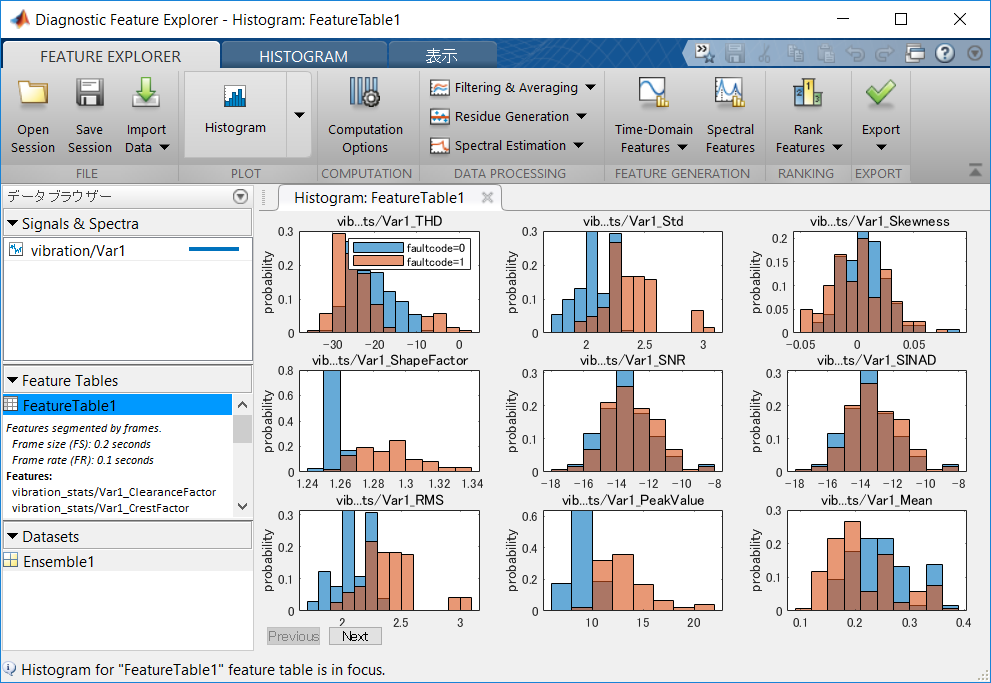

load('FeatureTable.mat');
disp(FeatureTable1(1:5,:))

    FRM_1_TimeStart    FRM_1_TimeEnd    FRM_1_vibration_stats_Var1_ClearanceFactor    FRM_1_vibration_stats_Var1_CrestFactor    FRM_1_vibration_stats_Var1_ImpulseFactor    FRM_1_vibration_stats_Var1_Kurtosis    FRM_1_vibration_stats_Var1_Mean    FRM_1_vibration_stats_Var1_PeakValue    FRM_1_vibration_stats_Var1_RMS    FRM_1_vibration_stats_Var1_SINAD    FRM_1_vibration_stats_Var1_SNR    FRM_1_vibration_stats_Var1_ShapeFactor    FRM_1_vibration_stats_Var1_Skewness    FRM_1_vibration_stats_Var1_Std    FRM_1_vibration_stats_Var1_THD    faultcode
    _______________    _____________    __________________________________________    ______________________________________    ________________________________________    ___________________________________    _______________________________    ____________________________________    ______________________________    ________________________________    ______________________________    ______________________________________    ___________________

## 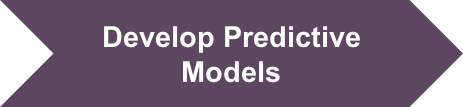

## Train, compare and select classifier 

Having an initial set of features, we can proceed to the next phase of the machine learning workflow, the training of various predictive models. You can use the [Classification Learner App](https://www.mathworks.com/help/stats/classificationlearner-app.html) to interactively train, compare and select classifiers.

classificationLearner

Select the `FeatureTable1` variable from the workspace as your data, and either hold out 30% as model "validation" data, or (to preserve more data for training) choose cross validation. 

Then train a bunch of different classifiers, including linear regression, SVM, and decision trees. Note which ones deliver higher accuracy on the held out validation data. Also explore the confusion matrices and conceptualize what misclassifying a normal versus an abnormal vibration means in practice.

To improve model performance, the following sections will apply additional optimization steps. Generate `trainClassifier.m` from the app that reproduces the trained classifier of your choice.

## 

## Split data into training and testing sets. 

These optimization steps need to be performed programmatically. Therefore, we first need to split the data like we did within the Classification Learner app, and to match our work in the app, holding out 30% of the (training) data for testing. Use [cvpartition](https://www.mathworks.com/help/stats/cvpartition.html) to split data into training and testing sets. Use [tabulate](https://www.mathworks.com/help/stats/tabulate.html) to see number of observations for each class.

rng(1)
% Use 30% of data for training and remaining for testing
split_data = cvpartition(FeatureTable1.faultcode, 'Holdout', 0.3);
% Create a training set
trainingData = FeatureTable1(split_data.training, :);
% Create a test set (won't be used until much later)
testingData = FeatureTable1(split_data.test, :);
tabulate(trainingData.faultcode)

     Value    Count   Percent
    normal       91     52.00%
  abnormal       84     48.00%


Let's reproduce the confusion matrix of the classifier of your choice from the Classification Learner App. Note that `trainedClassifier `is the auto generate function from the app.

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.18286 |     0.11921 |     0.18286 |     0.18286 |            4 |     spearman |


|    2 | Accept |     0.22857 |     0.13638 |     0.18286 |     0.18467 |            1 |  correlation |


|    3 | Accept |     0.21143 |     0.29639 |     0.18286 |     0.18294 |           79 |       cosine |


|    4 | Accept |     0.27429 |     0.14153 |     0.18286 |     0.18582 |           49 |  mahalanobis |


|    5 | Accept |     0.21143 |     0.20731 |     0.18286 |     0.20299 |            5 |     spearman |


|    6 | Best   |     0.14857 |     0.13822 |     0.14857 |     0.14858 |            3 |     spearman |


|    7 | Accept |     0.18286 |     0.15869 |     0.14857 |     0.14859 |            2 |     spearman |


|    8 | Accept |     0.15429 |     0.13222 |     0.14857 |     0.14858 |           29 |       cosine |


|    9 | Accept |     0.17714 |     0.11335 |     0.14857 |     0.14858 |           21 |       cosine |


|   10 | Best   |     0.11429 |     0.12005 |     0.11429 |      0.1143 |           38 |       cosine |


|   11 | Accept |     0.12571 |     0.12901 |     0.11429 |     0.11431 |           44 |       cosine |


|   12 | Accept |     0.11429 |     0.16261 |     0.11429 |      0.1143 |           39 |       cosine |


|   13 | Accept |     0.15429 |     0.13077 |     0.11429 |      0.1143 |            9 |       cosine |


|   14 | Best   |    0.097143 |     0.15904 |    0.097143 |    0.097152 |            5 |       cosine |


|   15 | Best   |    0.085714 |     0.13887 |    0.085714 |    0.085724 |            4 |       cosine |


|   16 | Best   |    0.062857 |     0.11608 |    0.062857 |    0.062876 |            3 |       cosine |


|   17 | Accept |     0.11429 |     0.15833 |    0.062857 |    0.062882 |            2 |       cosine |


|   18 | Accept |     0.14286 |     0.11172 |    0.062857 |    0.062881 |            4 |    euclidean |


|   19 | Accept |     0.10286 |     0.13614 |    0.062857 |     0.06288 |            9 |    euclidean |


|   20 | Accept |    0.097143 |      0.1196 |    0.062857 |    0.062881 |           16 |    euclidean |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |     0.11429 |     0.14002 |    0.062857 |    0.062882 |           29 |    euclidean |


|   22 | Accept |     0.17143 |    0.094134 |    0.062857 |    0.062881 |           64 |    euclidean |


|   23 | Accept |     0.15429 |     0.11013 |    0.062857 |     0.06288 |            1 |    euclidean |


|   24 | Accept |         2.4 |     0.14237 |    0.062857 |    0.096877 |           13 |      hamming |


|   25 | Accept |     0.15429 |      0.1176 |    0.062857 |    0.096877 |            1 |   seuclidean |


|   26 | Accept |        0.12 |     0.11549 |    0.062857 |    0.096877 |            5 |    minkowski |


|   27 | Accept |     0.26286 |     0.10853 |    0.062857 |    0.096871 |            1 |    chebychev |


|   28 | Accept |     0.10286 |     0.12491 |    0.062857 |    0.096871 |            1 |    cityblock |


|   29 | Accept |      1.4857 |    0.084921 |    0.062857 |    0.096859 |            1 |      jaccard |


|   30 | Accept |        0.52 |     0.15948 |    0.062857 |    0.096193 |           88 |    cityblock |


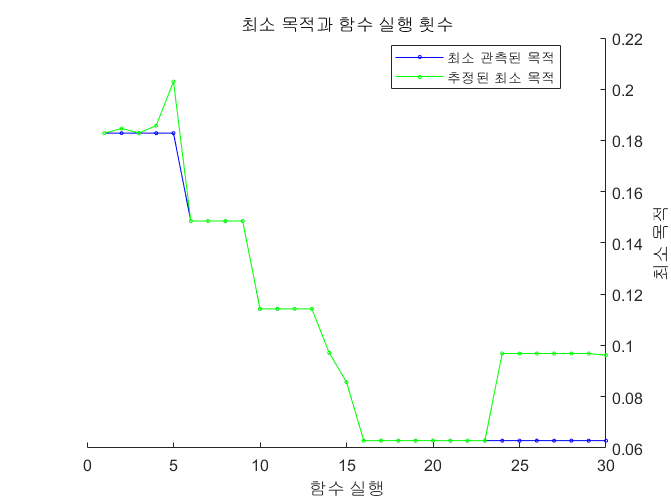

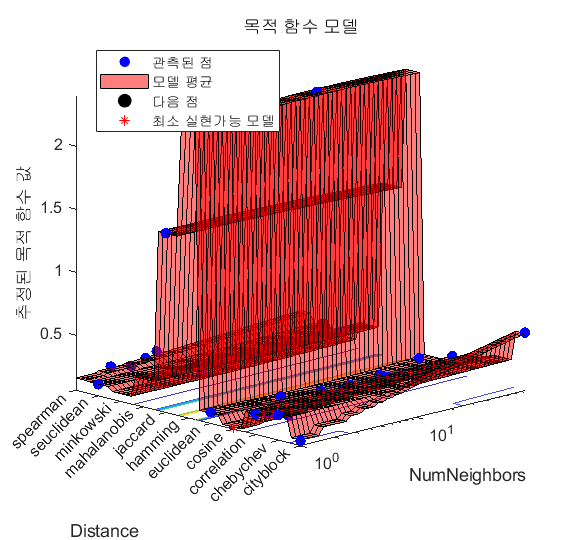


__________________________________________________________
최적화가 완료되었습니다.
MaxObjectiveEvaluations 30회에 도달했습니다.
총 함수 실행 횟수: 30
총 경과 시간: 64.7352초
총 목적 함수 실행 시간: 4.1231

최선의 관측된 실현가능점:
    NumNeighbors    Distance
    ____________    ________

         3           cosine 

관측된 목적 함수 값 = 0.062857
추정된 목적 함수 값 = 0.096193
함수 실행 시간 = 0.11608

최선의 추정된 실현가능점(모델에 따라 다름):
    NumNeighbors    Distance
    ____________    ________

         3           cosine 

추정된 목적 함수 값 = 0.096193
추정된 함수 실행 시간 = 0.13711



trained_model = trainClassifier(trainingData);

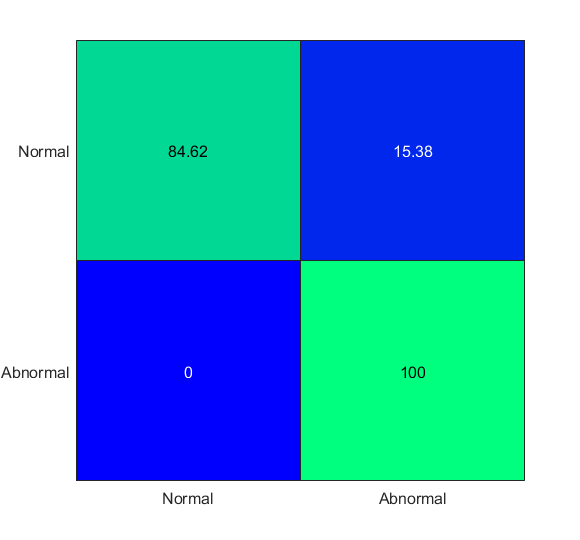

predictedCode = trained_model.predictFcn(testingData);
plot_confusionheatmap(testingData.faultcode, predictedCode)

A fairly high number of abnormal vibrations are misclassified as normal

## 

## Optimization 1: Train the classifier with misclassification cost

To bias the classifier towards fewer misclassifications of abnormal vibrations, we use a cost function that assigns higher misclassification cost, say double, to the 'Abnormal' class. We continue with the k-nearest neighbor. Note that misclassification of abnormal vibration decreases and that of normal vibration increases.

Retrain the model and check the confusion matrix.

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.18286 |     0.12958 |     0.18286 |     0.18286 |            4 |  correlation |


|    2 | Accept |     0.49714 |     0.11157 |     0.18286 |     0.19535 |           76 |     spearman |


|    3 | Best   |    0.062857 |     0.14777 |    0.062857 |    0.082016 |            2 |   seuclidean |


|    4 | Accept |     0.14857 |     0.12575 |    0.062857 |    0.074463 |           45 |       cosine |


|    5 | Accept |        0.08 |     0.11344 |    0.062857 |    0.063098 |            3 |   seuclidean |


|    6 | Accept |    0.091429 |    0.097603 |    0.062857 |    0.063073 |            1 |    minkowski |


|    7 | Accept |        0.52 |     0.12096 |    0.062857 |     0.06291 |           88 |    minkowski |


|    8 | Accept |    0.091429 |     0.10102 |    0.062857 |     0.06292 |            2 |       cosine |


|    9 | Accept |        0.08 |     0.10991 |    0.062857 |    0.062914 |            3 |    euclidean |


|   10 | Accept |     0.11429 |    0.094722 |    0.062857 |    0.062927 |           42 |    euclidean |


|   11 | Accept |      1.4286 |      0.1015 |    0.062857 |    0.063385 |            5 |      hamming |


|   12 | Accept |     0.14286 |     0.10981 |    0.062857 |    0.063341 |            4 |    chebychev |


|   13 | Accept |    0.062857 |     0.14017 |    0.062857 |    0.062879 |            4 |    cityblock |


|   14 | Accept |     0.23429 |     0.12133 |    0.062857 |    0.062879 |            1 |  mahalanobis |


|   15 | Accept |        0.52 |     0.11373 |    0.062857 |    0.062881 |           88 |      jaccard |


|   16 | Accept |        0.52 |     0.09919 |    0.062857 |    0.062942 |           88 |    cityblock |


|   17 | Best   |    0.017143 |     0.10777 |    0.017143 |    0.017081 |            1 |    cityblock |


|   18 | Accept |        0.52 |     0.18811 |    0.017143 |    0.017108 |           88 |    chebychev |


|   19 | Accept |        0.52 |     0.13265 |    0.017143 |    0.017112 |           87 |  mahalanobis |


|   20 | Accept |        0.52 |     0.10787 |    0.017143 |    0.017124 |           88 |  correlation |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |     0.19429 |    0.088111 |    0.017143 |    0.017136 |            1 |    chebychev |


|   22 | Accept |        0.52 |     0.11045 |    0.017143 |    0.017142 |           88 |   seuclidean |


|   23 | Accept |     0.25143 |     0.12548 |    0.017143 |    0.017146 |            1 |  correlation |


|   24 | Accept |     0.30857 |     0.13968 |    0.017143 |    0.017147 |            1 |     spearman |


|   25 | Accept |      1.4286 |     0.12554 |    0.017143 |    0.017142 |            1 |      jaccard |


|   26 | Accept |    0.091429 |     0.11525 |    0.017143 |    0.017134 |            1 |    euclidean |


|   27 | Accept |     0.11429 |    0.098189 |    0.017143 |    0.017124 |            8 |       cosine |


|   28 | Accept |    0.028571 |     0.10255 |    0.017143 |    0.017261 |            2 |    cityblock |


|   29 | Accept |    0.017143 |     0.12511 |    0.017143 |    0.017202 |            1 |    cityblock |


|   30 | Accept |    0.068571 |     0.11675 |    0.017143 |    0.017202 |            4 |    minkowski |


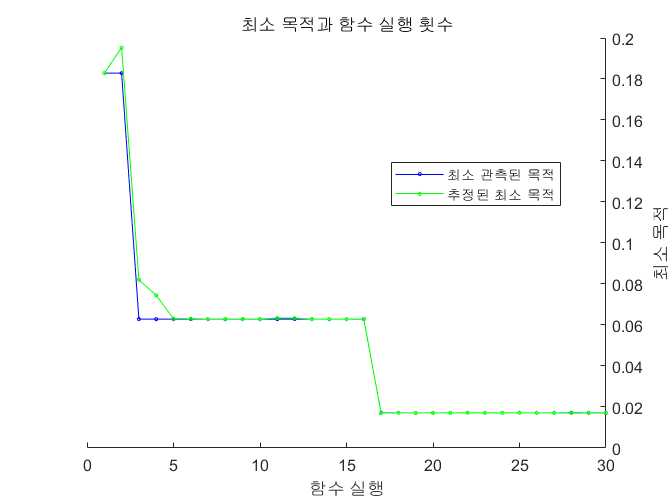

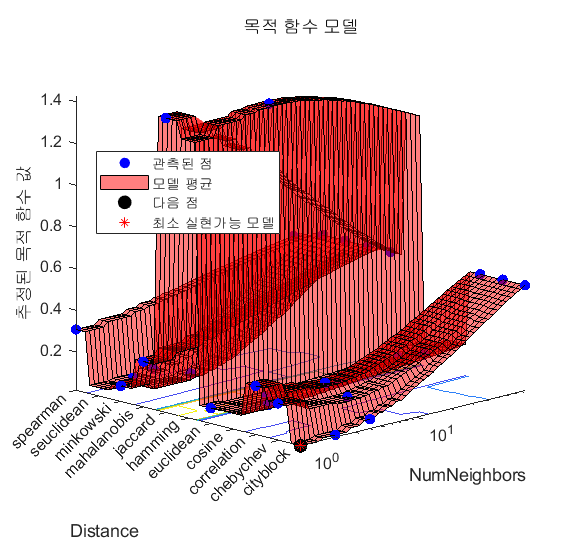


__________________________________________________________
최적화가 완료되었습니다.
MaxObjectiveEvaluations 30회에 도달했습니다.
총 함수 실행 횟수: 30
총 경과 시간: 57.7505초
총 목적 함수 실행 시간: 3.5215

최선의 관측된 실현가능점:
    NumNeighbors    Distance 
    ____________    _________

         1          cityblock

관측된 목적 함수 값 = 0.017143
추정된 목적 함수 값 = 0.017202
함수 실행 시간 = 0.10777

최선의 추정된 실현가능점(모델에 따라 다름):
    NumNeighbors    Distance 
    ____________    _________

         1          cityblock

추정된 목적 함수 값 = 0.017202
추정된 함수 실행 시간 = 0.11597



trained_model = trainClassifier(trainingData);

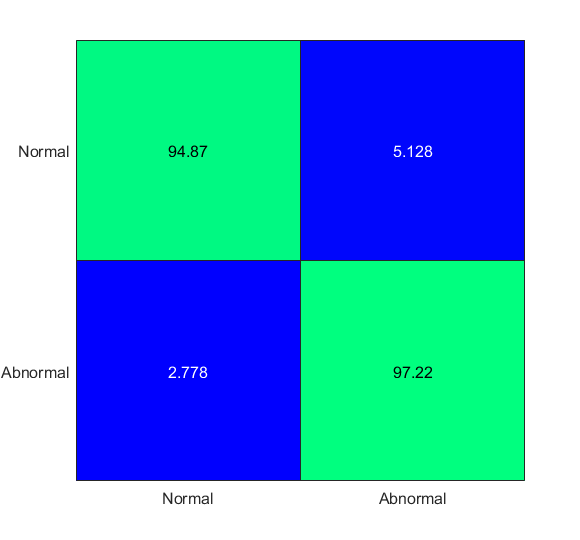


predictedCode = trained_model.predictFcn(testingData);
plot_confusionheatmap(testingData.faultcode, predictedCode)

## Optimization 2: Hyperparameter tuning

We perform hyperparameter tuning by using [Bayesian Optimization](https://www.mathworks.com/help/stats/bayesian-optimization-workflow.html) to find optimal values for model parameters. 

Retrain the model and check the confusion matrix.

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |     0.14286 |     0.22012 |     0.14286 |     0.14286 |           73 |    cityblock |


|    2 | Accept |     0.18286 |     0.21501 |     0.14286 |     0.14567 |            2 |    chebychev |


|    3 | Best   |    0.097143 |     0.15874 |    0.097143 |    0.097573 |           10 |    euclidean |


|    4 | Accept |     0.13143 |     0.12063 |    0.097143 |    0.097317 |            2 |  mahalanobis |


|    5 | Accept |         2.4 |    0.074261 |    0.097143 |     0.59063 |           10 |      hamming |


|    6 | Accept |        0.52 |    0.099014 |    0.097143 |     0.14996 |           88 |  mahalanobis |


|    7 | Accept |        0.52 |    0.090862 |    0.097143 |     0.15971 |           88 |    minkowski |


|    8 | Accept |        0.28 |    0.087614 |    0.097143 |     0.16273 |            1 |       cosine |


|    9 | Accept |        0.52 |     0.10499 |    0.097143 |     0.17122 |           87 |  correlation |


|   10 | Accept |        0.52 |     0.16151 |    0.097143 |     0.18083 |           88 |   seuclidean |


|   11 | Accept |     0.33714 |     0.13205 |    0.097143 |     0.18673 |            1 |     spearman |


|   12 | Accept |        0.52 |    0.088611 |    0.097143 |     0.19664 |           88 |      jaccard |


|   13 | Accept |     0.22286 |    0.083934 |    0.097143 |    0.097277 |            1 |    euclidean |


|   14 | Accept |     0.22286 |    0.088943 |    0.097143 |    0.097319 |            1 |    cityblock |


|   15 | Accept |        0.52 |     0.14151 |    0.097143 |     0.20757 |           88 |    euclidean |


|   16 | Accept |        0.52 |    0.089553 |    0.097143 |      0.2113 |           88 |    chebychev |


|   17 | Accept |     0.22286 |     0.14049 |    0.097143 |    0.097331 |            1 |    cityblock |


|   18 | Accept |        0.52 |     0.12708 |    0.097143 |    0.097339 |           88 |       cosine |


|   19 | Accept |        0.52 |     0.09411 |    0.097143 |    0.097348 |           88 |     spearman |


|   20 | Best   |        0.08 |    0.076206 |        0.08 |    0.080077 |           11 |    cityblock |


|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|   21 | Accept |     0.22286 |    0.079953 |        0.08 |    0.080078 |            1 |    minkowski |


|   22 | Accept |     0.22286 |    0.093099 |        0.08 |    0.080078 |            1 |   seuclidean |


|   23 | Accept |         1.6 |      0.1001 |        0.08 |    0.080066 |            1 |      jaccard |


|   24 | Accept |     0.26286 |    0.084293 |        0.08 |    0.080067 |            1 |  correlation |


|   25 | Accept |     0.34286 |    0.095646 |        0.08 |    0.080028 |            1 |  mahalanobis |


|   26 | Accept |        0.12 |     0.13074 |        0.08 |    0.080028 |            7 |  mahalanobis |


|   27 | Accept |     0.10286 |    0.087032 |        0.08 |    0.080031 |            4 |    euclidean |


|   28 | Accept |     0.12571 |    0.081158 |        0.08 |    0.080031 |            6 |    minkowski |


|   29 | Accept |     0.12571 |    0.095504 |        0.08 |    0.080031 |            6 |   seuclidean |


|   30 | Accept |    0.091429 |    0.077477 |        0.08 |    0.080069 |           24 |    cityblock |


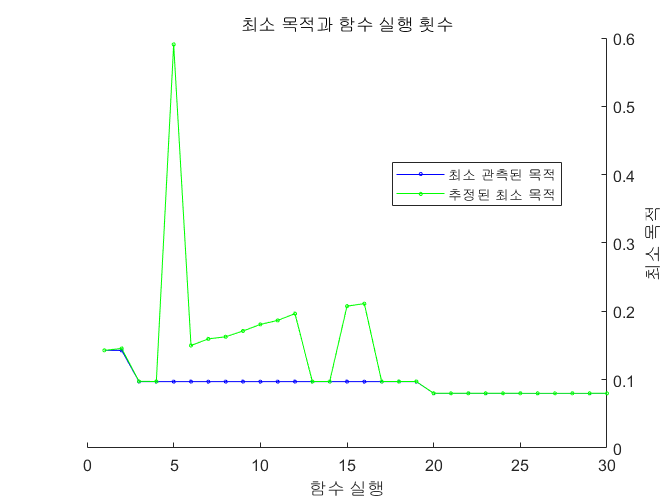

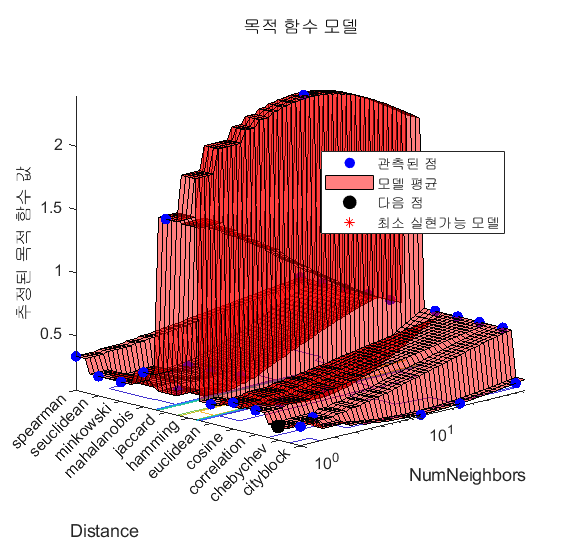


__________________________________________________________
최적화가 완료되었습니다.
MaxObjectiveEvaluations 30회에 도달했습니다.
총 함수 실행 횟수: 30
총 경과 시간: 52.5668초
총 목적 함수 실행 시간: 3.3203

최선의 관측된 실현가능점:
    NumNeighbors    Distance 
    ____________    _________

         11         cityblock

관측된 목적 함수 값 = 0.08
추정된 목적 함수 값 = 0.080069
함수 실행 시간 = 0.076206

최선의 추정된 실현가능점(모델에 따라 다름):
    NumNeighbors    Distance 
    ____________    _________

         11         cityblock

추정된 목적 함수 값 = 0.080069
추정된 함수 실행 시간 = 0.10567



trained_model = trainClassifier(trainingData);

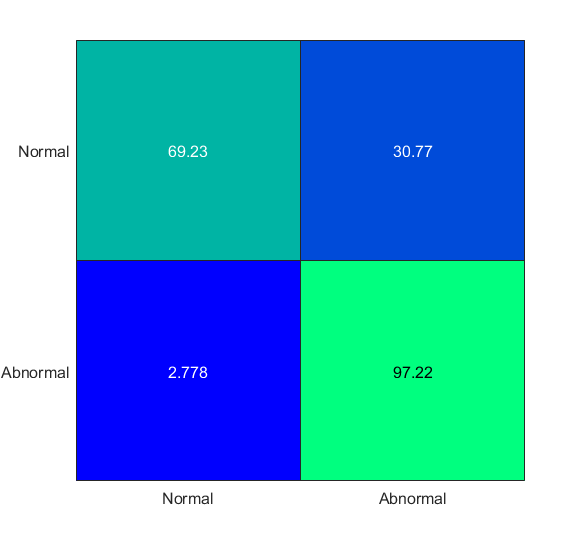

predictedCode = trained_model.predictFcn(testingData);
plot_confusionheatmap(testingData.faultcode, predictedCode)

Comparing with the original model, you can see that misclassification of abnormal and normal vibration are both descreased.

## 

## [Optional] Perform feature selection using Neighborhood Component Analysis

In this optional section we explore training a more compact model that uses only a subset of the 15 features, namely the features that have the majority of the predictive power. [Neighborhood Component Analysis](https://www.mathworks.com/help/stats/neighborhood-component-analysis.html) (NCA) is an automated approach for  selecting a small subset of features that carry information most relevant to the classification task while minimizing redudancy among selected features. 

flagNCA = false;
if ~flagNCA 
    selected_feature_indx = 3:15;
    
else % Perform feature selection with neighborhood component analysis
    X = table2array(trainingData(:,3:15));
    Y = table2array(trainingData(:,16));
    mdl = fscnca(X, Y, 'Lambda', 1e-4, 'Verbose', 0);
    
    % Select features with weight above 0.1
    selected_feature_indx = find(mdl.FeatureWeights > 0.1) + 2;
    
    % Plot feature weights
    stem(mdl.FeatureWeights,'bo');
    save('SelectedFeatures.mat','selected_feature_indx');
    predName = trainingData.Properties.VariableNames(selected_feature_indx)

To actually get a more compact model for deployment, we retrain the model using only selected features. 

Retrain the model and check the confusion matrix.

    trained_model = trainClassifier_selected(trainingData,predName);
    predictedCode = trained_model.predictFcn(testingData);
    plot_confusionheatmap(testingData.faultcode, predictedCode)
end

## 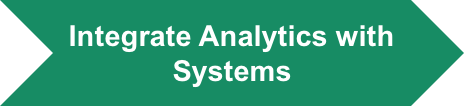

## Code Generation

Generate C code that takes the extracted features as input and produces vibration classification label as output. In practice, putting the feature extraction part into the generated C code is desiable for many cases but we leave it out for the sake of simplicity.

Check the name of the trained model. 

    trained_model

You may need to rewrite the model name (`ClassificationKNN` below) to the name of the model.

    % Save trained model as a compact model for code generation
    saveCompactModel(trained_model.ClassificationKNN,'ClassificationModel')

We use MATLAB Coder app available in MATLAB Coder. The app helps go through the required setting to generate C code from MATLAB function, `classifyVibration.m`

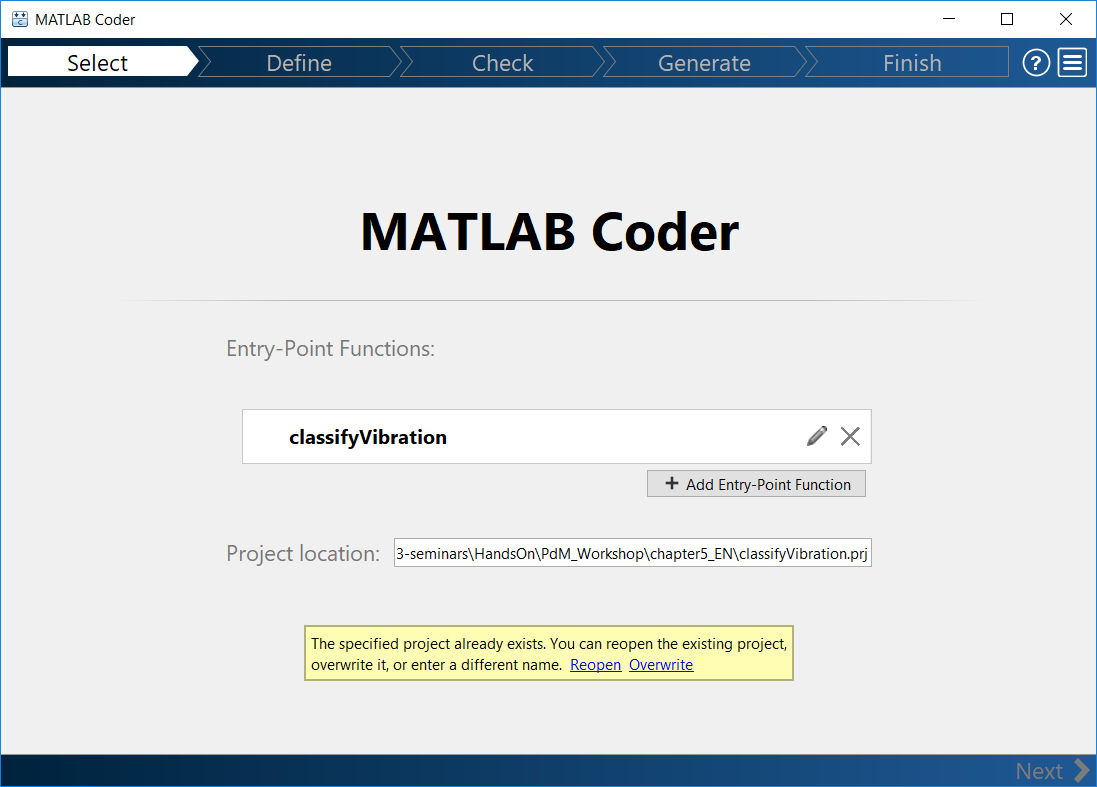

## 

## Validate final model

Process the validation set by calling the mex version of the function `classifyVibration.m`

    idx = 36;
    predictedCode = classifyVibration_mex(testingData{idx,selected_feature_indx});
    disp("Prediction： " + string(predictedCode) + " / Ground Truth: " + string(testingData.faultcode(idx)))

*Copyright 2019 The MathWorks, Inc.*